# Data analysis of localization confidence

- Compares confidence between unimodal and bimodal conditions

clear; clc; close all;
sub_slc     = 4;
ses_slc     = 1;

% manage path
cur_dir      = pwd;
[project_dir, ~]= fileparts(fileparts(cur_dir));
out_dir      = fullfile(cur_dir, 's1Fig');
addpath(genpath(fullfile(project_dir,'func')))
data_dir     = fullfile(project_dir, 'data','biLoc');
if ~exist(out_dir,'dir') mkdir(out_dir); end

% organize data
[bi_resp, bi_conf, bi_err, ExpInfo] = org_data(sub_slc,ses_slc,'biLoc');
[uni_resp, uni_conf, uni_err, uniExpInfo, ~, ScreenInfo] = org_data(sub_slc,[],'uniLoc');

% conditions
seq         = ExpInfo.randAVIdx;
audIdx      = ExpInfo.audIdx;
visIdx      = ExpInfo.visIdx;
cueIdx      = ExpInfo.cueIdx;
visReliIdx  = ExpInfo.visReliIdx;
num_rep     = ExpInfo.nRep;
deg_per_px  = rad2deg(atan(170 / 2 / ExpInfo.sittingDistance)) .* 2 / ScreenInfo.xaxis;cue_label   = {'Post-cue: A','Post-cue: V'};
rel_label   = {'High visual reliability','Low visual reliability'};
aud_locs    = ExpInfo.speakerLocVA(ExpInfo.audIdx);
remapped_vis_locs = ExpInfo.targetPixel .* deg_per_px;

% summarize unimodal data
% condition (A,V1,V2) x loc (4) x rep
uni_pconf = mean(mean(uni_conf,3),2);
uni_idx = [1,1;2,3];

% organize by discrepancy
[conf_by_diff, diff_locs] = org_by_diffs(bi_conf, aud_locs); % {diff} cue x reliability x rep 

% summarize ventriloquist effect
% condition (A,V1,V2) x loc (4) x rep
a_uni = mean(squeeze(uni_resp(1,:,:)),2);
v1_uni = mean(squeeze(uni_resp(2,:,:)),2);
v2_uni = mean(squeeze(uni_resp(3,:,:)),2);
uni = {a_uni, a_uni; v1_uni', v2_uni'};
for cue = 1:2
    for rel = 1:2
        subset_bi_resp = squeeze(mean(bi_resp(:, :, cue, rel, :),5));
        if cue == 1
            uni_repeated = repmat(uni{cue, rel}, [1, size(bi_resp, 2)]);
            % ve(:,:,cue, rel) = subset_bi_resp - aud_locs';
        elseif cue == 2
            % uni_repeated = repmat(uni{cue, rel}, [size(bi_resp, 1),1]);
            uni_repeated = ExpInfo.targetPixel .* deg_per_px;
            % ve(:,:,cue, rel) = subset_bi_resp - aud_locs;
        end
        ve(:,:,cue, rel) = (subset_bi_resp - uni_repeated);
    end
end
[ve_by_diff, raw_diff] = org_by_raw_diffs(ve, aud_locs); % {diff} cue x reliability x rep
raw_diff(2,:) = -raw_diff;
raw_diff = -raw_diff;

## Plot set up

lw = 2;
fontSZ = 15;
titleSZ = 20;
dotSZ = 80;
clt = [30, 120, 180; % blue
    227, 27, 27;  % dark red
    repmat(125, 1, 3)]./255; % gray
%     251, 154, 153]./255; % light red


## Sanity check: localization response

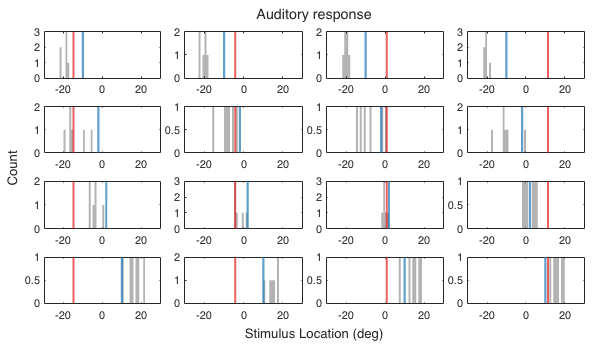

figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Auditory response')
xlabel(t, 'Stimulus Location (deg)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
         curr_resp = squeeze(bi_resp(a, v, 1, 1, :));
         nexttile
         h = histogram(curr_resp, numel(curr_resp),'BinWidth',1);
         h.FaceColor = repmat(0.5, 1, 3); 
         h.EdgeColor = 'none';

         xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
         xline(remapped_vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

         xlim([-30, 30])
    end
end

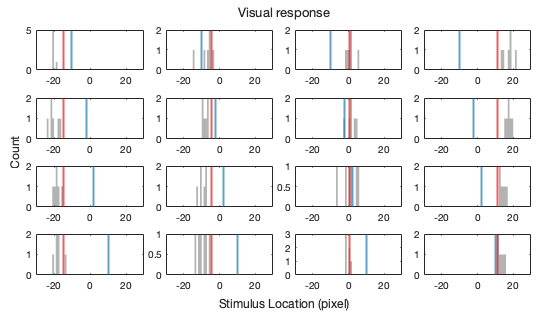



figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Visual response')
xlabel(t, 'Stimulus Location (pixel)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
         curr_resp = squeeze(bi_resp(a, v, 2, 2, :));
         nexttile
         h = histogram(curr_resp, numel(curr_resp),'BinWidth',1);
         h.FaceColor = repmat(0.5, 1, 3); 
         h.EdgeColor = 'none';

         xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
         xline(remapped_vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

         xlim([-30, 30])
    end
end

## Is confidence modulated by cue discrepancy and cue reliability?

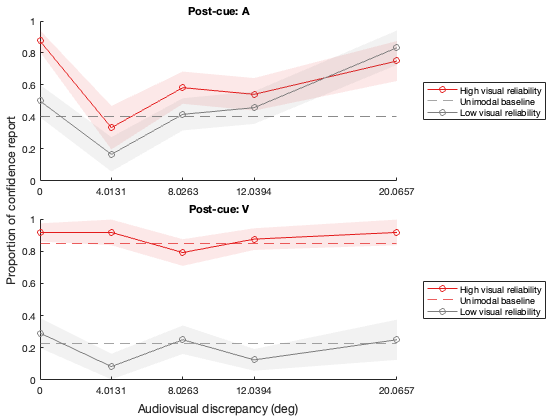

figure; hold on 

t = tiledlayout(2, 1);
xlabel(t, 'Audiovisual discrepancy (deg)');
ylabel(t, 'Proportion of confidence report');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:numel(cueIdx)
    nexttile
    title(cue_label{cue})
    hold on
    for rel = 1:numel(visReliIdx)
        [mean_p, sd_p] = deal(NaN(1, numel(diff_locs)));
        for diff = 1:numel(diff_locs)
            est = squeeze(conf_by_diff{diff}(cue, rel, :))';
            p = sum(est)/numel(est);
            mean_p(diff) = p;
            sd_p(diff) = sqrt((p*(1-p))/numel(est));
        end
        plot(diff_locs, mean_p,'-o', 'Color',clt(rel+1,:))
        patch([diff_locs, fliplr(diff_locs)], ...
            [mean_p - sd_p, fliplr(mean_p + sd_p)], ...
            clt(rel+1,:),'EdgeColor','none','FaceAlpha',0.1, ...
            'HandleVisibility', 'off')
        
        if cue == 1
            yline(uni_pconf(1),'--','Color',repmat(0.5,1,3))
        else
            yline(uni_pconf(rel+1),'--','Color',clt(rel+1,:))
        end
        
        ylim([0, 1])
        xlim([min(diff_locs), max(diff_locs)])
    end
    xticks(diff_locs)
    legend({'High visual reliability','Unimodal baseline','Low visual reliability'}, 'Location', 'eastoutside');
end

## Ventriloquist effect

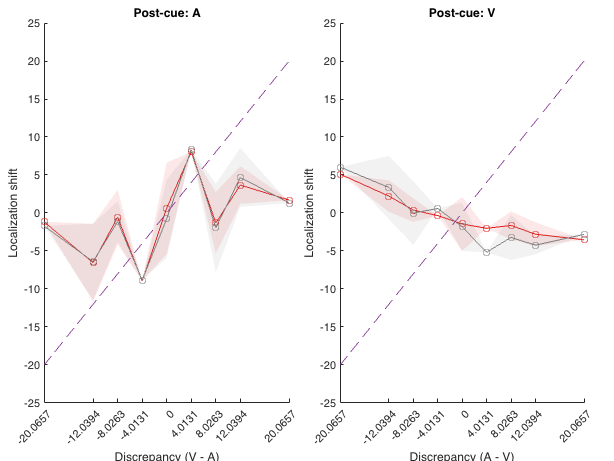

figure
t = tiledlayout(1,2);
% xlabel(t, 'Audiovisual discrepancy (pixel)');
% ylabel(t, 'Proportion of confidence report');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:numel(cueIdx)
    nexttile
    title(cue_label{cue})
    hold on
    for rel = 1:numel(visReliIdx)
        [mean_ve, sd_ve] = deal(NaN(1, numel(raw_diff(cue,:))));
        for diff = 1:numel(raw_diff(cue,:))
            i_ve = squeeze(ve_by_diff{diff}(cue, rel, :))';
            mean_ve(diff) = mean(i_ve);
            sd_ve(diff) = std(i_ve);
        end

        plot(raw_diff(cue,:), mean_ve,'-o', 'Color',clt(rel+1,:))
        hold on
        
        patch([raw_diff(cue,:), fliplr(raw_diff(cue,:))], ...
            [mean_ve - sd_ve, fliplr(mean_ve + sd_ve)], ...
            clt(rel+1,:),'EdgeColor','none','FaceAlpha',0.1, ...
            'HandleVisibility', 'off')
        plot(linspace(min(raw_diff(cue,:)),max(raw_diff(cue,:)),10),linspace(min(raw_diff(cue,:)),max(raw_diff(cue,:)),10),'--')
        xlim([min(raw_diff(cue,:)), max(raw_diff(cue,:))])
    end
    xticks(sort(raw_diff(cue,:)))
    ylabel('Localization shift')
    if cue == 1
        xlabel('Discrepancy (V - A)')
    else
        xlabel('Discrepancy (A - V)')
    end
    % legend([rel_label{1} ], 'Location', 'northeast');
end